clear all;
close all;

in = [200, 100, 100]

in =    200   100   100


HSV_fix_pix(in)

Cdelta =     0.3906

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 19
        FractionLength: 18

V =     0.7812

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 18
        FractionLength: 18

S =      1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 18
        FractionLength: 0

ans =      0
   255
   200


rgb2hsv(in/256)

ans =          0    0.5000    0.7812


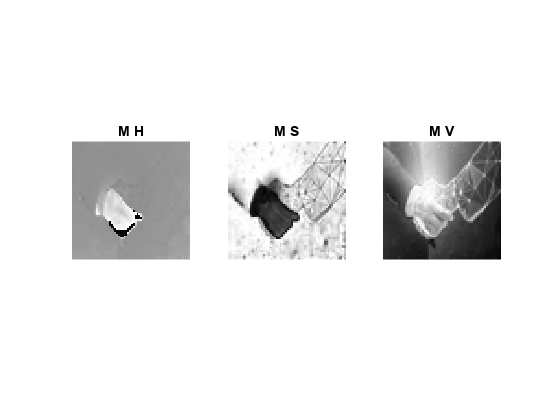

hand = imread("hand.jpg");
hand64 = imresize(hand,[64 64]);

hand64_hsv_m = rgb2hsv(hand64);
figure
subplot(1, 3, 1)
imshow(hand64_hsv_m(:, :, 1), 'InitialMagnification', 400)
title("M H")
subplot(1, 3, 2)
imshow(hand64_hsv_m(:, :, 2), 'InitialMagnification', 400)
title("M S")
subplot(1, 3, 3)
imshow(hand64_hsv_m(:, :, 3), 'InitialMagnification', 400)
title("M V")

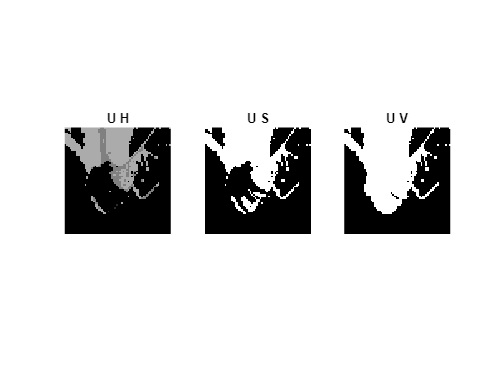


hand64_hsv = RGB2HSV_fix_img(hand64);

figure
subplot(1, 3, 1)
imshow(hand64_hsv(:, :, 1), 'InitialMagnification', 400)
title("U H")
subplot(1, 3, 2)
imshow(hand64_hsv(:, :, 2), 'InitialMagnification', 400)
title("U S")
subplot(1, 3, 3)
imshow(hand64_hsv(:, :, 3), 'InitialMagnification', 400)
title("U V")

function [out] = HSV_fix_pix(in)
    
    out = [0; 0; 0];
    in = in(:, :);
    R = fi(in(1)/256, 0, 18, 18);
    G = fi(in(2)/256, 0, 18, 18);
    B = fi(in(3)/256, 0, 18, 18);
    
    Cmax = max([R, G, B]);

    Cmin = min([R, G, B]);

    Cdelta = Cmax - Cmin

    %VVVVVVVVVVVVV

    V = Cmax

    %SSSSSSSSSSSSS
    if (V == 0)
        S = fi(0, 0, 18, 17)
    else
        S = fi((Cmax-Cmin), 0, 18, 18) / Cmax
    end %if


    %HHHHHHHHHHHHH
    if (Cdelta == fi(0, 0, 18, 18))
        H = fi(0, 1, 18, 14);
    elseif (Cmax == R)
        H = fi(((G-B)/Cdelta), 1, 18, 14);
    elseif (Cmax == G)
        H = fi(((B-R)/Cdelta + 2), 1, 18, 14);
    elseif (Cmax == B)
        H = fi(((R-G)/Cdelta + 4), 1, 18, 14);
    end

    if (H < 0)
        H = H + 6;
    end % if

    H = H/6;

    out(1) = cast((H*256), 'uint8');
    out(2) = cast((S*256), 'uint8');
    out(3) = cast((V*256), 'uint8');
end %HSV


function [out] = HSV_pix(in)
    
    out = [0; 0; 0];
    in = in(:, :);
    R = double(in(1))/256;
    G = double(in(2))/256;
    B = double(in(3))/256;
    
    Cmax = max([R, G, B]);

    Cmin = min([R, G, B]);

    Cdelta = Cmax - Cmin;

    %VVVVVVVVVVVVV

    V = Cmax;

    %SSSSSSSSSSSSS
    if (V == 0)
        S = 0;
    else
        S = (V-Cmin) / V;
    end %if


    %HHHHHHHHHHHHH
    if (Cdelta == 0)
        H = 0;
    elseif (Cmax == R)
        H = ((G-B)/Cdelta);
    elseif (Cmax == G)
        H = ((B-R)/Cdelta + 2);
    elseif (Cmax == B)
        H = ((R-G)/Cdelta + 4);
    end

    if (H < 0)
        H = H + 6;
    end % if

    H = H/6;

    out(1) = cast((H*256), 'uint8');
    out(2) = cast((S*256), 'uint8');
    out(3) = cast((V*256), 'uint8');
end %HSV


function [out_img] = RGB2HSV_fix_img(in_img)
out_img = zeros(size(in_img));
for i = 1:64
    for j = 1:64
        out_img(i, j, :) = HSV_fix_pix(in_img(i, j, :));
    end %for
end %for
out_img = cast(out_img, 'uint8');
end


function [out_img] = RGB2HSV_img(in_img)
out_img = zeros(size(in_img));
for i = 1:64
    for j = 1:64
        out_img(i, j, :) = HSV_pix(in_img(i, j, :));
    end %for
end %for
out_img = cast(out_img, 'uint8');
end